# Example illustrating orbital stability/instability

Consider the PDE 

#### 
$$i \partial_t \Phi + \triangle \Phi + 2\left| \Phi\right|^2 \Phi=0$$
 

on the dumbbell quantum graph. This has a constant-amplitude solution $\Phi = c e^{i \Omega t}$ with $\Omega = -2 c^2$, which is linearly stable for $c < 0.121$. At the critical value $\Omega = \frac{\omega_1}{2}$ where $\omega_1=-0.0586$is the frequency of the first excited state of the linear problem. 

We do two numerical simulations. In the first, the constant solution is linearly stable and we will show it is also orbitally stable.

In the second, the constant solution is linearly unstable, so the analysis used to show orbital stability doesn't work.

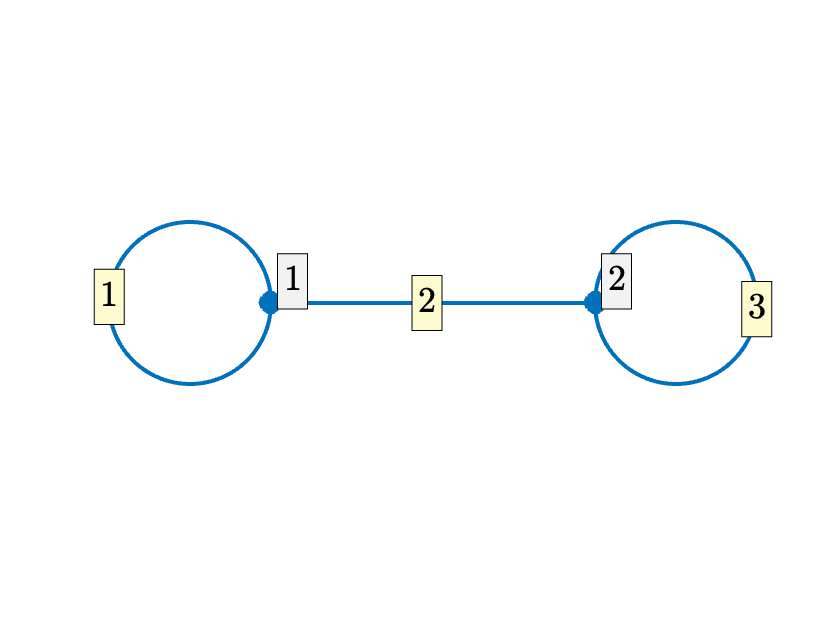

L = [2*pi 4 2*pi];
G=quantumGraphFromTemplate('dumbbell','LVec',L);
G.plot('layout'); 

V=G.eigs(2);
groundState=V(:,1);
perturbation= V(:,2);
mu = -1i;
F =@(z) -2i * z.^2 .* conj(z);
[~,~,nxTotal]=G.nx;

## Linearly and orbitally stable dynamics, 

First we set $c=0.05$, which is linearly and neutrally stable. We will also demonstrate it's orbitally stable.

epsilon = 0.05;
c = 0.05;
omega = -2*c^2;
PhiLead=c*ones(nxTotal,1);
phi0 =PhiLead+epsilon*perturbation;

Set up time stepping

tFinal = 2000;
tPrint = 4;
dt = 0.02;
nSkip=round(tPrint/dt);
[t,Phi] = G.qgdeSDIRK443(mu,F,tFinal,phi0,dt,'nSkip',nSkip);
nT = length(t);

At each saved time step, we find the value of $\theta$ that minimizes the objective function $f(\theta) = ||\Phi(t)-e^{i\theta}\Phi(0)||$. We use this to define a measure of orbital distance `PhiDiffOrbital, `which we compare to` PhiDiffAbsolute` defined as $||\Phi(t)-\Phi(0)||$. We also project the solution onto the first two eigenfunctions, defining

$A_j = \langle\Phi(t),\phi_j\rangle$ for j=0 and j=1. We decompose the ground state into polar coordinates $A_0 = \rho_0 e^{i \theta_0}$ and then mod out the phase of the excited state, defining $B_1 = e^{-i\theta_0}A_1$

PhiPert=zeros(nxTotal,nT);
PhiDiffOrbital=zeros(nT,1);
PhiDiffAbsolute=zeros(nT,1);
A0=zeros(nT,1);
A1=zeros(nT,1);
theta = zeros(nT,1);
for k=1:nT
    objective = @(theta)G.norm(Phi(:,k)-exp(1i*theta)*PhiLead);
    [theta(k),PhiDiffOrbital(k)]=fminbnd(objective,-0.1,2*pi-0.1);
    PhiPert(:,k)=Phi(:,k)-exp(1i*theta(k))*PhiLead;
    PhiDiffAbsolute(k)=G.norm(Phi(:,k)-exp(1i*omega*t(k))*PhiLead);
    A0(k)=G.dot(Phi(:,k),groundState);
    A1(k)=G.dot(Phi(:,k),perturbation);
end
theta=unwrap(theta);
theta0=unwrap(angle(A0));
B1=A1.*exp(-1i*theta0);

#### Plot the phase difference between the perturbed and unperturbed solutions

The solution is simulated for a long time to allow the stable exact solution and the computed perturbed solution to get completely out of phase, which happens slowly.

plot(t,theta-omega*t')
xlabel('$t$')
ylabel('Phase difference')

#### Plot the orbital and absolute difference between the stable exact solution and the numerical solution

The orbital distance stays bounded by the initial conditions, but the absolute distance grows because the two solutions go out of phase.

plot(t,PhiDiffOrbital,t,PhiDiffAbsolute,'--')
xlabel('$t$')
legend('Orbital distance $\min_{\theta}||\Phi(t)-\Phi_{\rm Lead}e^{i\theta}||$', ...
    'Absolute Distance $||\Phi(t)-\Phi_{\rm Lead}e^{i\omega t}||$', ...
    'Location','northwest')

#### Plot the projection onto the ground-state and first excited state

This plot shows that the amplitude of the constant part and the projection onto the first non-constant eigenfunctions remain at their initial order of magnitude. The perturbation is about 1/4 the amplitude of the unperturbed solution.

plot(t,abs(A0),t,abs(A1)); xl=get(gca,'ylim'); set(gca,'ylim',[0 xl(2)]); %
xlabel('$t$')
legend('$|c_0(t)|$','$|c_1(t)|$')

#### The phase-corrected real and imaginary parts of the projection onto the first excited state.

These do not grow, and instead simply oscillate harmonically.

plot(real(B1),imag(B1)); axis equal
xlabel('Re $c_1$')
ylabel('Im $c_1$')

## Linearly and orbitally unstable dynamics, 

Next, we set $c=0.2$, which is unstable. The initial perturbation is quite small

c = 0.2;
omega = -2*c^2;
epsilon = 0.02;
PhiLead=c*ones(nxTotal,1);
phi0 =PhiLead+epsilon*perturbation;
tFinal = 500;
tPrint = 5;
dt = 0.02;
nSkip=round(tPrint/dt);
[t,Phi] = G.qgdeSDIRK443(mu,F,tFinal,phi0,dt,'nSkip',nSkip);
nT = length(t);
PhiPert=zeros(nxTotal,nT);
PhiDiffOrbital=zeros(nT,1);
PhiDiffAbsolute=zeros(nT,1);
A0=zeros(nT,1);
A1=zeros(nT,1);
theta = zeros(nT,1);
for k=1:nT
    objective = @(theta)G.norm(Phi(:,k)-exp(1i*theta)*PhiLead);
    [theta(k),PhiDiffOrbital(k)]=fminbnd(objective,-0.1,2*pi-0.1);
    PhiPert(:,k)=Phi(:,k)-exp(1i*theta(k))*PhiLead;
    PhiDiffAbsolute(k)=G.norm(Phi(:,k)-exp(1i*omega*t(k))*PhiLead);
    A0(k)=G.dot(Phi(:,k),groundState);
    A1(k)=G.dot(Phi(:,k),perturbation);
end
theta=unwrap(theta);
theta0=unwrap(angle(A0));
B1=A1.*exp(-1i*theta0);

#### Plot the phase difference between the perturbed and unperturbed solutions

We see these get out of phase much faster

plot(t,theta-omega*t')
xlabel('$t$')
ylabel('Phase difference')

#### Plot the orbital and absolute difference between the stable exact solution and the numerical solution

Both distances grow to O(1) pretty fast. The orbital distance is the distance in an appropriate rotating reference frame, and shows the dynamics more clearly.

plot(t,PhiDiffOrbital,t,PhiDiffAbsolute,'--')
xlabel('$t$')
legend('Orbital distance $\min_{\theta}||\Phi(t)-\Phi_{\rm Lead}e^{i\theta}||$', ...
    'Absolute Distance $||\Phi(t)-\Phi_{\rm Lead}e^{i\omega t}||$')

#### Plot the projection onto the ground-state and first excited state

Here we see that there is significant exchange of energy between the two modes

plot(t,abs(A0),t,abs(A1),'--')
xlabel('$t$')
legend('$|c_0(t)|$','$|c_1(t)|$')

#### Plot the phase-corrected real and imaginary parts fo the projection onto the first excited state. 

Rather than oscillating with near-constant amplitude around the origin as in the stable case, the solution appears to follow a homoclinic curve.

plot(real(B1),imag(B1),'.','markersize',12);
xlabel('Re $c_1$')
ylabel('Im $c_1$')

## Change the phase of the perturbation

The only change we make here is to change the phase of the perturbation

c = 0.2;
omega = -2*c^2;
epsilon = 0.02;
PhiLead=c*ones(nxTotal,1);

Right here is the change, we multiply the perturbation term by a factor of $\sqrt{-1}$. Let's see what happens. We also choose a slightly larger perturbation for reasons of visualization

phi0 =PhiLead+1i*epsilon*perturbation;
tFinal = 500;
tPrint = 5;
dt = 0.025;
nSkip=round(tPrint/dt);
[t,Phi] = G.qgdeSDIRK443(mu,F,tFinal,phi0,dt,'nSkip',nSkip);
nT = length(t);
PhiPert=zeros(nxTotal,nT);
PhiDiffOrbital=zeros(nT,1);
PhiDiffAbsolute=zeros(nT,1);
A0=zeros(nT,1);
A1=zeros(nT,1);
theta = zeros(nT,1);
for k=1:nT
    objective = @(theta)G.norm(Phi(:,k)-exp(1i*theta)*PhiLead);
    [theta(k),PhiDiffOrbital(k)]=fminbnd(objective,-0.1,2*pi-0.1);
    PhiPert(:,k)=Phi(:,k)-exp(1i*theta(k))*PhiLead;
    PhiDiffAbsolute(k)=G.norm(Phi(:,k)-exp(1i*omega*t(k))*PhiLead);
    A0(k)=G.dot(Phi(:,k),groundState);
    A1(k)=G.dot(Phi(:,k),perturbation);
end
theta=unwrap(theta);
theta0=unwrap(angle(A0));
C1=A1.*exp(-1i*theta0);

#### Plot the phase difference between the perturbed and unperturbed solutions

We see these get out of phase much faster

plot(t,theta-omega*t')
xlabel('$t$')
ylabel('Phase difference')

#### Plot the orbital and absolute difference between the stable exact solution and the numerical solution

Both distances grow to O(1) pretty fast. The orbital distance is the distance in an appropriate rotating reference frame, and shows the dynamics more clearly.

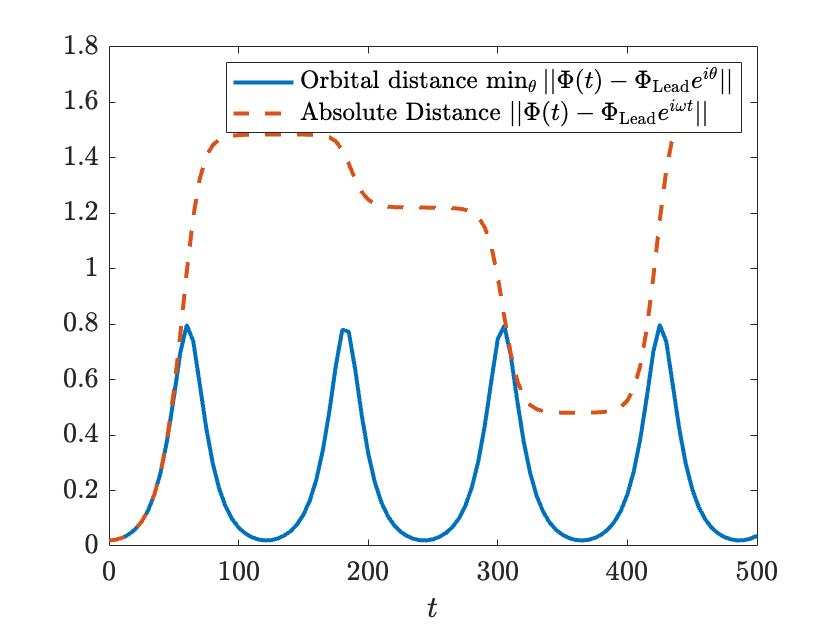

plot(t,PhiDiffOrbital,t,PhiDiffAbsolute,'--')
xlabel('$t$')
legend('Orbital distance $\min_{\theta}||\Phi(t)-\Phi_{\rm Lead}e^{i\theta}||$', ...
    'Absolute Distance $||\Phi(t)-\Phi_{\rm Lead}e^{i\omega t}||$')

#### Plot the projection onto the ground-state and first excited state

Here we see that there is significant exchange of energy between the two modes

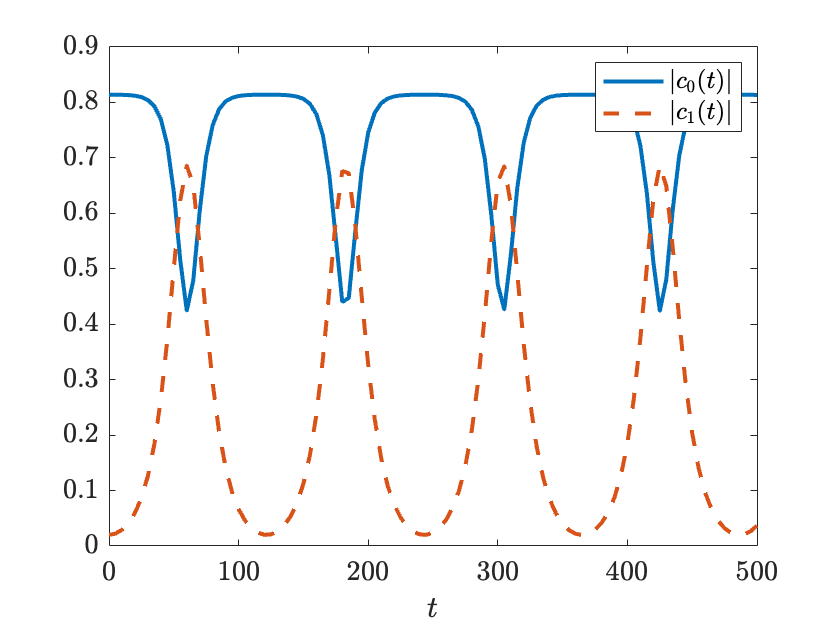

plot(t,abs(A0),t,abs(A1),'--')
xlabel('$t$')
legend('$|c_0(t)|$','$|c_1(t)|$')

#### Plot the phase-corrected real and imaginary parts fo the projection onto the first excited state. 

Rather than oscillating with near-constant amplitude around the origin as in the stable case, the solution appears to follow a homoclinic cycle.

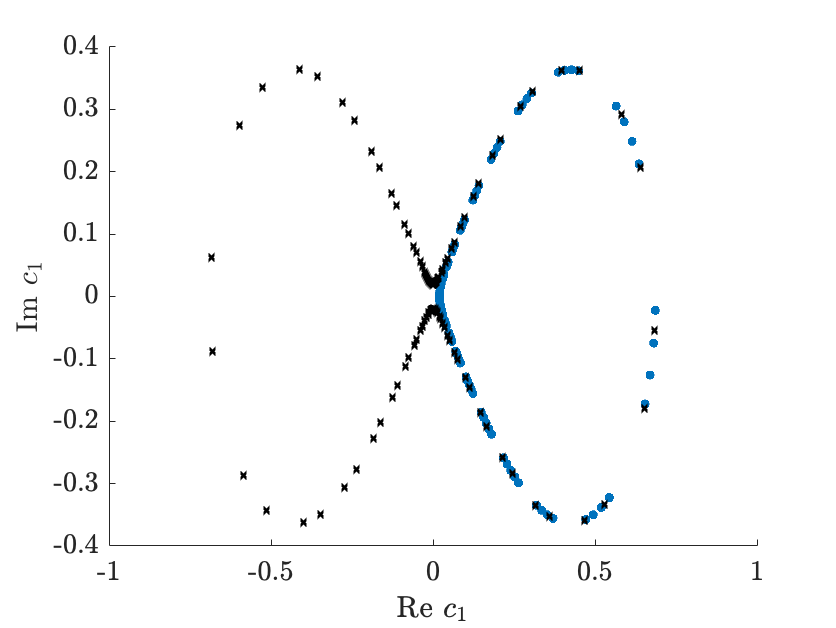

figure;clf;hold on;
plot(real(B1),imag(B1),'.','markersize',12)
plot(real(C1),imag(C1),'kx','markersize',3);
xlabel('Re $c_1$')
ylabel('Im $c_1$')